# Autoencoder airfoil generator

## Train an autoencoder

unzip('airfoils.zip', 'airfoils');
encoder = train_selig('airfoils', chebyshevs(5), 5, 100, 'MaxEpochs', 10000);

## Set parameter variables (live reload)

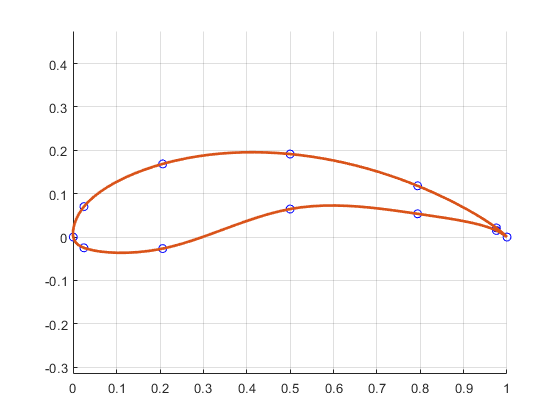

a1 = 0.882;
a2 = 0.174;
a3 = 0.028;
a4 = 0.162;
a5 = 0.107;
ch_xx = chebyshevs(5);
af = (decode(encoder, [a1; a2; a3; a4; a5])/100)';
ex_xx = [ 1 fliplr(ch_xx) 0 ch_xx 1];
ex_yy = [0 af(1:5) 0 af(6:10) 0];
clf
hold on
plot(ex_xx, ex_yy, 'bo');
curve = cscvn([ex_xx;ex_yy]);
fnplt(curve)
hold off
axis equal
grid on

Set all parameters (live reload)

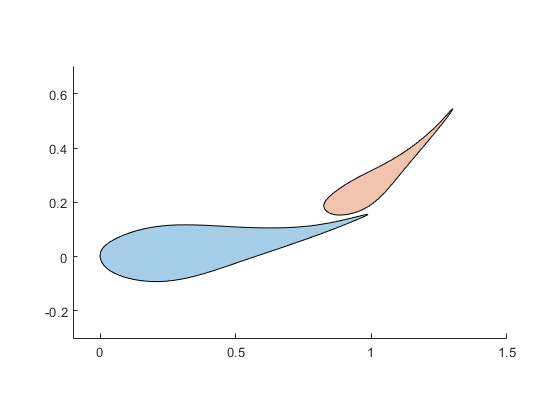

e1_1 = 0.257;
e1_2 = 0.153;
e1_3 = 0.092;
e1_4 = 0.367;
e1_5 = 0.117;
e2_1 = 0.251;
e2_2 = 0.099;
e2_3 = 0.178;
e2_4 = 0.428;
e2_5 = 0.068;
a1 = 9;
a2 = 38;
x2 = 0.16;
y2 = 0.02;
s2 = 0.6;
ch_xx = chebyshevs(5);
el1 = decodeAirfoil(encoder, [e1_1; e1_2; e1_3; e1_4; e1_5], 0.01, ch_xx);
el2 = decodeAirfoil(encoder, [e2_1; e2_2; e2_3; e2_4; e2_5], 0.01, ch_xx);
[e1m, e2m] = twoairfoils(el1, a1, el2, a2, x2, y2, s2);
plot([e1m e2m])
axis equal
xlim([-0.1 1.5])
ylim([-0.3 0.7])

## sda

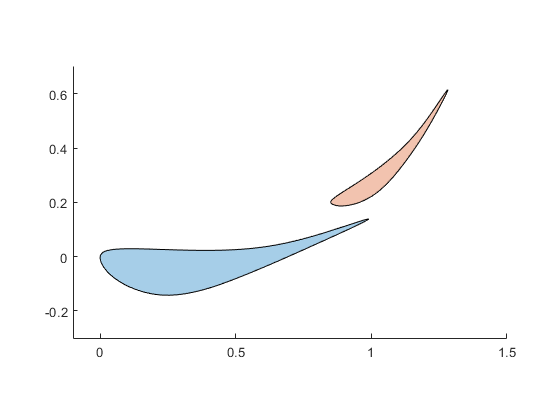

e1_1 = 0.05;
e1_2 = 0;
e1_3 = 0.123;
e1_4 = 0.233;
e1_5 = 0.117;
e2_1 = 0;
e2_2 = 0.068;
e2_3 = 0.092;
e2_4 = 0.282;
e2_5 = 0.068;
a1 = 8;
a2 = 44;
x2 = 0.14;
y2 = 0.06;
s2 = 0.6;

el1 = decodeAirfoil(encoder, [e1_1; e1_2; e1_3; e1_4], 0.01, ch_xx);
el2 = decodeAirfoil(encoder, [e2_1; e2_2; e2_3; e2_4], 0.01, ch_xx);
[e1m, e2m] = twoairfoils(el1, a1, el2, a2, x2, y2, s2);
plot([e1m e2m])
axis equal
xlim([-0.1 1.5])
ylim([-0.3 0.7])